# Compile Figures for Upper Kuparuk River Basin, Alaska

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'figures/';

%What is the original data?
originaldata = {'UK_synthesized_data.txt'};

%do you want the figure saved?
printfig  = true ;

%Where do you want to save files?
workdirfigures = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years/';

%Where is your data?
workdir = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years/Rresults/';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Lets plot the results

I know the units of Q, what should the units of P be? Rainfall is at units of mm, but is that per second? The ReadMe file says precipitation is recorded hourly and nothing more. The data file says units of [mm] recorded every hour, so is it per hour? Also it says its resolution is 0.1 mm per tip. What does per tip mean?

Catchment Size of Upper Kuparuk Basin at Gauge Site is 142km^2.

From Kane:

"2007 was a relatively dry year, although all three years were below the average rainfall (222 mm). The main storage mechanism for the Upper Kuparuk is the active layer. While positive storage followed immediately after snowmelt, relative storage went from positive to negative during the summer and remained negative for the remainder of the summer as ET + Q exceeded P. The timing of this transition was later for those years with greater rainfall. Note that a large tundra wildfire in 2007 northwest of the Upper Kuparuk burned from early summer into early winter, and was the largest documented fire on the North Slope of Alaska. 





% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2*2};
FS = {'FontSize',10*3,15*3,18*3,21*3,30*3};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};
Colors = [203,201,226;
158,154,200;
106,81,163;
186,228,179;
116,196,118;
35,139,69;
253,190,133;
253,141,60;
217,71,1;
189,215,231;
107,174,214;
33,113,181
28,144,153]./255;

%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 1.1;
axt = 0.8;
axl = 1.2;
axr = 2.0;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;


% %set figure page
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


years = [2005 2007:2017];
maxRRD = zeros(size(years));
maxRRDlgt = zeros(size(years));

%state the range of lag time to consider
hourrange = [0 30];
hourlimit = 0;


for jj = 1:numel(years) 
str = {'1hr_simple_',mat2str(years(jj)),'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),maxRRDse(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_years(filename,workdir,Colors(jj,:),hourlimit,hourrange);

end
if hourlimit
    xline(hourrange(1),'LineWidth',3,'Color',[0.65 0.85 0.90])
    xline(hourrange(2),'LineWidth',3,'Color',[0.65 0.85 0.90])
end

set(gca, LW{[1,4]},'XLim',[0,max(max(lagt))],'Ylim',[0, max(maxRRD+maxRRDse)],TL{:},FS{[1,5]});
ax = gca;  % or use specific axes handle
ax.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

%set axis
xlabel('Lag time [h]',TX{:},FS{[1,5]},UN{[1,3]});
ylabel('RRD [1/h]',TX{:},FS{[1,5]},UN{[1,3]});
[lgd, hobj, ~, ~] =legend(num2str(years.'), 'Location', 'northeast','NumColumns', 2,TX{:});

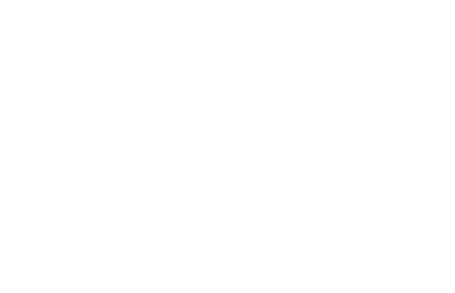

adjustLegendSize(lgd,hobj,1.05,1.00,10,1);
% legend(num2str(years.'), 'NumColumns', 2);

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

# Plot the lag hour with each year

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

hold on
for jj = 1:numel(years)
    plot(years(jj),maxRRDlgt(jj),'.','MarkerSize',35*2,'Color',Colors(jj,:))
end
set(gca, LW{[1,4]},'XLim',[min(years),max(years)],'Ylim',[0, max(maxRRDlgt)],TL{:},FS{[1,5]});
% ax = gca;  % or use specific axes handle
% ax.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

%set axis
xlabel('Year',TX{:},FS{[1,5]},UN{[1,3]});
ylabel('Lag time [h]',TX{:},FS{[1,5]},UN{[1,3]});
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'laghour_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

# Plot max RRD with each year

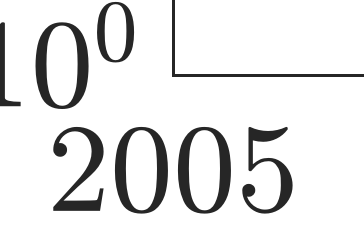

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
errorbar(years,maxRRD,maxRRDse,'.k','MarkerSize',100,'LineWidth',6)

for jj = 1:numel(years)
    plot(years(jj),maxRRD(jj),'.','MarkerSize',45*2,'Color',Colors(jj,:))
end
set(gca, LW{[1,4]},'XLim',[min(years),max(years)],'Ylim',[0, max(maxRRD+maxRRDse)],TL{:},FS{[1,5]});
ax = gca;  % or use specific axes handle
ax.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

%set axis
xlabel('Year',TX{:},FS{[1,5]},UN{[1,3]});
ylabel('Peak RRD [1/h]',TX{:},FS{[1,5]},UN{[1,3]});
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'maxRRD_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

# How does max RRD change with Active Layer Thickness

% load('/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/UK/UK_ActiveLayer.mat')
% thickingrate = Poly(:,1);
%set figure page
% f3 = figure;
% set(f3,'Units','Inches','Position',[0.7 12 fw fh]);
% set(f3,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
% set(f3,'Color','w','InvertHardcopy','off', 'MenuBar','none');
% set(f3,'Resize','off','Toolbar','none');
% ax = axes('Units','Inches','position',[axl axb axw axh]);
% hold on
% AL_index = zeros(size(years_available));
% RRD_index = zeros(size(years));
% 
% for l = 1: numel(years_available)
%         logindx = sum(years == years_available(l))==1; %where the active layer matches RRD
%         AL_index(l) = logindx;
% end
% for l = 1:numel(years)
%     logindx = sum(years_available == years(l))==1; %where the active layer matches RRD
%     RRD_index(l) = logindx;
% end
% 
%     plot(meanActiveLayer(logical(AL_index)),maxRRD(logical(RRD_index)),'.','MarkerSize',35)
% set(gca,'XLim',[min(meanActiveLayer),max(meanActiveLayer)],'Ylim',[0, max(maxRRD)],TL{:},FS{[1,4]});
% 
% %set axis
% xlabel('Active Layer Thickness [cm]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
% ylabel('max RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
%   
% 
% %Save figure
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'mRRD_ActiveLayer' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f3,format,resl,rend,figname,'-loose');
% end

### Combining Active Layer Thickness and Lag Hour with year 

% f4 = figure;
% set(f4,'Units','Inches','Position',[0.7 12 fw fh]);
% set(f4,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
% set(f4,'Color','w','InvertHardcopy','off', 'MenuBar','none');
% set(f4,'Resize','off','Toolbar','none');
% ax = axes('Units','Inches','position',[axl axb axw axh]);
% hold on
% yyaxis left
% plot(years,maxRRDlgt,'.','MarkerSize',35)
% set(gca,'Ylim',[0, max(maxRRDlgt)*1.1],TL{:},FS{[1,4]});
% %set axis
% ylabel('Lag Hour',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
% 
% yyaxis right
% plot(years_available(logical(AL_index)),meanActiveLayer(logical(AL_index)),'.','MarkerSize',35);
% set(gca,'Ylim',[0, max(meanActiveLayer)*1.1],TL{:},FS{[1,4]});
% ylabel('Active Layer Thickness [cm]',TX{:},FS{[1,4]},UN{[1,3]});
% 
% xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
% 
% 
% %Save figure
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'laghour_ActiveLayer_year' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f4,format,resl,rend,figname,'-loose');
% end

### Combining Active Layer Thickness and RRD max with year

% f4 = figure;
% set(f4,'Units','Inches','Position',[0.7 12 fw fh]);
% set(f4,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
% set(f4,'Color','w','InvertHardcopy','off', 'MenuBar','none');
% set(f4,'Resize','off','Toolbar','none');
% ax = axes('Units','Inches','position',[axl axb axw axh]);
% hold on
% yyaxis left
% plot(years,maxRRD,'.','MarkerSize',35)
% set(gca,'Ylim',[0, max(maxRRD)*1.1],TL{:},FS{[1,4]});
% %set axis
% ylabel('max RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
% 
% yyaxis right
% plot(years_available(logical(AL_index)),meanActiveLayer(logical(AL_index)),'.','MarkerSize',35);
% set(gca,'Ylim',[0, max(meanActiveLayer)*1.1],TL{:},FS{[1,4]});
% ylabel('Active Layer Thickness [cm]',TX{:},FS{[1,4]},UN{[1,3]});
% 
% xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
% 
% 
% %Save figure
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'maxRRD_ActiveLayer_year' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f4,format,resl,rend,figname,'-loose');
% end
% 

#### How does rate of active layer thickenning compare to maxRRD

% 
% f5 = figure;
% set(f5,'Units','Inches','Position',[0.7 12 fw fh]);
% set(f5,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
% set(f5,'Color','w','InvertHardcopy','off', 'MenuBar','none');
% set(f5,'Resize','off','Toolbar','none');
% ax = axes('Units','Inches','position',[axl axb axw axh]);
% hold on
% 
% plot(thickingrate(logical(AL_index),1),maxRRD(logical(RRD_index)),'.','MarkerSize',35)
% set(gca,'XLim',[min(thickingrate(logical(AL_index),1)),max(thickingrate(logical(AL_index),1))],'Ylim',[0, max(maxRRD)],TL{:},FS{[1,4]});
% 
% %set axis
% xlabel('Active Layer Thicknenning rate [cm/time]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
% ylabel('max RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
%   
% 
% %Save figure
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'mRRD_ActiveLayerrate' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f5,format,resl,rend,figname,'-loose');
% end
% 

#### How does rate of active layer thickenning compare to Lag Hour

% 
% f5 = figure;
% set(f5,'Units','Inches','Position',[0.7 12 fw fh]);
% set(f5,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
% set(f5,'Color','w','InvertHardcopy','off', 'MenuBar','none');
% set(f5,'Resize','off','Toolbar','none');
% ax = axes('Units','Inches','position',[axl axb axw axh]);
% hold on
% 
% plot(thickingrate(logical(AL_index),1),maxRRDlgt(logical(RRD_index)),'.','MarkerSize',35)
% set(gca,'XLim',[min(thickingrate(logical(AL_index),1)),max(thickingrate(logical(AL_index),1))],'Ylim',[0, max(maxRRDlgt)],TL{:},FS{[1,4]});
% 
% %set axis
% xlabel('Active Layer Thicknening rate [cm/time]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
% ylabel('lag hour',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
%   
% 
% %Save figure
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'laghour_ActiveLayerrate' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f5,format,resl,rend,figname,'-loose');
% end


precip = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/precipitation.mat");
Precip = precip.P;
short_t_cont = precip.short_t_cont_num;
Pyears = precip.years;
Pmonths = precip.months;
temp = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/airtemperature.mat");
airtemp = temp.airtemp;
discharge = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/discharge.mat");
Q = discharge.Q;
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

years = years;
for l = 1: numel(years)
        logindxYears = (Pyears == years(l));
        logindxMonths = (Pmonths > 5 & Pmonths<10);
        logindxMonthsJ = (Pmonths <= 5 );
        totaldata(l) = sum(logindxYears);
        totalP(l) = nansum(Precip(logindxYears));
        totalT(l) = nanmean(airtemp(logindxYears & logindxMonths));
        totalTJuly(l) = nanmean(airtemp(logindxYears & logindxMonthsJ));
        %%%%% here consider November and December by doing 
        logindxYears_prev = (Pyears == years(l)-1); 
        logindxMonthsW_prev = (Pmonths > 10);
        winter_temp = [airtemp(logindxYears & logindxMonthsJ); airtemp(logindxYears_prev & logindxMonthsW_prev)];
        av_winter(l) = nanmean(winter_temp);

        Q_year = Q(logindxYears);
        P_year = Precip(logindxYears);
        time = short_t_cont(logindxYears);
     

        % Define the number of hours in a week
            hours_per_week = 168;

        % Reshape the data into a matrix with one week per column
            num_weeks = floor(length(Q_year)/hours_per_week);
            time_matrix = reshape(time(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            Q_matrix = reshape(Q_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            P_matrix = reshape(P_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);

        % Calculate the mean of each column to get the weekly averages
            time_weekly_averages = nanmean(time_matrix, 1);
            Q_weekly_averages = nanmean(Q_matrix, 1);
            P_weekly_averages = nanmean(P_matrix, 1);
            maxQ(l) = max(Q_weekly_averages);

        subplot(2, 6, l)
%          figtQP_plot_UK_wiMatlab_years(time_weekly_averages,Q_weekly_averages,P_weekly_averages,.3)
        figtQP_plot_UK_wiMatlab_years(time,Q_year,P_year,16)
        title(years(l),TX{:},FS{[1,4]},UN{[1,3]})
%         xlabel('t',TX{:},FS{[1,4]},UN{[1,3]});
%         ylabel('Q $\&$ P [mm/h]',TX{:},FS{[1,4]},UN{[1,3]});
if l == 10
    xlabel('Months',TX{:},FS{[1,6]},UN{[1,3]},'Position',[0,-.3]);
end
if l == 1
    ylabel('Q $\&$ P [mm/h]',TX{:},FS{[1,6]},UN{[1,3]},'Position',[-.5,-.5]);
end

end
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'precip_discharge_years_avs' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

precip = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/precipitation.mat");
Precip = precip.P;
short_t_cont = precip.short_t_cont_num;
Pyears = precip.years;
Pmonths = precip.months;
temp = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/airtemperature.mat");
airtemp = temp.airtemp;
discharge = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/discharge.mat");
Q = discharge.Q;








f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

years = years;
for l = 1: numel(years)
        logindxYears = (Pyears == years(l));
        logindxMonths = (Pmonths > 5 & Pmonths<10);
        logindxMonthsJ = (Pmonths <= 5 );
        totaldata(l) = sum(logindxYears);
        totalP(l) = nansum(Precip(logindxYears));
        totalT(l) = nanmean(airtemp(logindxYears & logindxMonths));
        totalTJuly(l) = nanmean(airtemp(logindxYears & logindxMonthsJ)); 
        %%%%% here consider November and December by doing 
        logindxYears_prev = (Pyears == years(l)-1); 
        logindxMonthsW_prev = (Pmonths > 10);
        winter_temp = [airtemp(logindxYears & logindxMonthsJ); airtemp(logindxYears_prev & logindxMonthsW_prev)];
        av_winter(l) = nanmean(winter_temp);
        Q_year = Q(logindxYears);
        P_year = Precip(logindxYears);
        time = short_t_cont(logindxYears);
     

        % Define the number of hours in a week
            hours_per_week = 168;

        % Reshape the data into a matrix with one week per column
            num_weeks = floor(length(Q_year)/hours_per_week);
            time_matrix = reshape(time(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            Q_matrix = reshape(Q_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            P_matrix = reshape(P_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);

        % Calculate the mean of each column to get the weekly averages
            time_weekly_averages = nanmean(time_matrix, 1);
            Q_weekly_averages = nanmean(Q_matrix, 1);
            P_weekly_averages = nanmean(P_matrix, 1);
            maxQ(l) = max(Q_weekly_averages);

        subplot(2, 6, l)
          figtQP_plot_UK_wiMatlab_years(time_weekly_averages,Q_weekly_averages,P_weekly_averages,.3)
%         figtQP_plot_UK_wiMatlab_years(time,Q_year,P_year,16)
        title(years(l),TX{:},FS{[1,4]},UN{[1,3]})
if l == 10
    xlabel('Months',TX{:},FS{[1,6]},UN{[1,3]},'Position',[0,-.3]);
end
if l == 1
    ylabel('Q $\&$ P [mm/h]',TX{:},FS{[1,6]},UN{[1,3]},'Position',[-.5,-.5]);
end

end

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'precip_discharge_years' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

% plot(av_winter, totalTJuly,'.','MarkerSize',35)

# What percent of precipitation is going to discharge each year? 

%Correct for data availability and check what percent of P goes to
%discharge, assuming no other contribution. 
years = years;
for l = 1: numel(years)
        isnansPQ = ~isnan(Precip) &~isnan(Q);
        logindxYears = (Pyears == years(l));
        logindxMonths = (Pmonths > 5 & Pmonths<9);
        logindxMissing = (~isnan(Precip) & ~isnan(Q));
        hourssum(l) = sum(logindxYears & logindxMonths);
        totaldata(l) = sum(logindxYears & logindxMonths & logindxMissing);
        totalP(l) = nansum(Precip(logindxYears & logindxMonths));
        totalQ(l) = nansum(Q(logindxYears &logindxMonths));
        totalmeanP(l)= nanmean(Precip(logindxYears & logindxMonths)).*hourssum(l);
        totalmeanQ(l) = nanmean(Q(logindxYears & logindxMonths)).*hourssum(l); %for 3 months
        PercentP(l) = totalQ(l)./totalP(l);
end
f2= figure

f2 =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

errorbar(PercentP,maxRRD,maxRRDse,'.k','MarkerSize',45*2,'LineWidth',6)
hold on
for l = 1:numel(years)
    hold on
plot(PercentP(l),maxRRD(l),'.','MarkerSize',35*2,'Color',Colors(l,:))
end
ylabel('Peak RRD [1/h]',TX{:},FS{[1,6]},UN{[1,3]});
xlabel('Annual Summer Q to P Ratio',TX{:},FS{[1,6]},UN{[1,3]})

ax.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

set(gca, LW{[1,4]},TL{:},FS{[1,4]});
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'Q2PRatio' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end


f2 = figure

f2 =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

% for l = 1:numel(years)
%     hold on
plot(years,totaldata./hourssum,'.k','MarkerSize',100)%,'Color',Colors(l,:))
% end
ylabel('Fraction of Hourly Summer Data Available',TX{:},FS{[1,5]},UN{[1,3]});
xlabel('Years',TX{:},FS{[1,5]},UN{[1,3]})
set(gca, LW{[1,4]},TL{:},FS{[1,5]});
% save('UK_data_availability',years,totaldata,hourssum,'-mat')
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'data_availability' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

f1=figure

f1 =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

for l = 1:numel(years)
    hold on
    plot(years(l),totalmeanQ(l),'.','MarkerSize',35,'Color',Colors(l,:))
end
ylabel('Annual Summer Discharge (Q) [mm]',TX{:},FS{[1,6]},UN{[1,3]});
xlabel('Years',TX{:},FS{[1,6]},UN{[1,3]})
set(gca, LW{[1,4]},TL{:},FS{[1,4]});

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'yrs_summerQ' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end


f1 = figure

f1 =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

plot(totalmeanP(2:end-1),totalmeanQ(3:end),'.','MarkerSize',35)
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'meanP_meanQ' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end


% ALT = meanActiveLayer(logical(AL_index));
%enough data?
% edat = totaldata./max(totaldata);
% totalP_ = totalP(edat>.05);
% maxRRD_ = maxRRD(edat>.05);

% Create a 1x4 set of plots
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

ax1=subplot(2, 2, 1)

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


plot(years,maxRRD,'.k','MarkerSize',35*2)
% title('maxRRD')
ylabel('Peak RRD [1/h]',TX{:},FS{[1,4]},UN{[1,3]})
xlabel('Years',TX{:},FS{[1,4]},UN{[1,3]})
set(ax1, LW{[1,4]},TL{:},FS{[1,4]});

ax1.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

ax2 = subplot(2, 2, 2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


plot(totalTJuly,maxRRD,'.','MarkerSize',35*2)
xlabel('Mean Temperature until July [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]})

set(ax2, LW{[1,4]},TL{:},FS{[1,4]});

ax2.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

ax3 = subplot(2, 2, 3)

ax3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


plot(totalP,maxRRD,'.','MarkerSize',35*2)
xlabel('Anticedent wetness [mm]',TX{:},FS{[1,4]},UN{[1,3]})
set(ax3,TL{:},FS{[1,4]});
ylabel('Peak RRD [1/h]',TX{:},FS{[1,4]},UN{[1,3]})

ax3.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

ax4 = subplot(2, 2, 4)

ax4 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


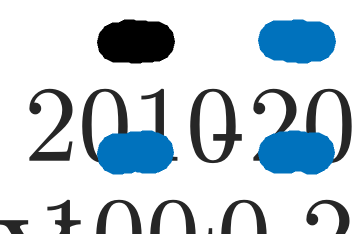

plot(maxQ,maxRRD,'.','MarkerSize',35*2)
xlabel('Snowmelt runoff [mm/h]',TX{:},FS{[1,4]},UN{[1,3]})
set(ax4,TL{:},FS{[1,4]});

ax4.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'maxRRD_eachvar' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

WinterTemp = av_winter; Precipitation = totalP; Snowmelt = maxQ; mRRD = maxRRD;
% T = table(WinterTemp',  Precipitation', Snowmelt', mRRD', 'VariableNames', {'WinterTemp', 'Precipitation','Snowmelt', 'mRRD'});
T = table(WinterTemp', Precipitation', mRRD', 'VariableNames', {'WinterTemp', 'Precipitation', 'mRRD'});

% Create the linear regression model
mdl = fitlm(T, 'mRRD ~ WinterTemp  + Precipitation ');

% Display the model coefficients
disp(mdl.Coefficients);

                      Estimate          SE         tStat      pValue  
                     ___________    __________    _______    _________

    (Intercept)        -0.011155     0.0050585    -2.2053     0.054865
    WinterTemp       -0.00069422     0.0002503    -2.7735     0.021628
    Precipitation     3.8627e-05    1.1714e-05     3.2975    0.0092672




% Display the R-squared value
disp(mdl.Rsquared.Adjusted);

    0.5613



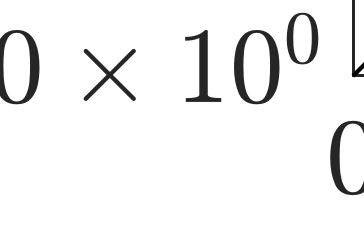



A = mdl.Coefficients.Estimate("WinterTemp");
B = mdl.Coefficients.Estimate("Precipitation");
% C = mdl.Coefficients.Estimate("Snowmelt");
D = mdl.Coefficients.Estimate("(Intercept)");
% RHS = A.*WinterTemp + B.*Precipitation + C.*Snowmelt + D;
% RHS = A.*WinterTemp + C.*Snowmelt  + D;
RHS = A.*WinterTemp + B.*Precipitation  + D;
f1 = figure; 
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

errorbar(RHS,maxRRD,maxRRDse,'.k','MarkerSize',100,LW{[1,4]})
hold on

for l = 1:numel(years)
    hold on
    plot(RHS(l),mRRD(l),'.','MarkerSize',35*2,'Color',Colors(l,:))
end
plot([0 .015],[0 .015],'-k','LineWidth',2)
axis equal
axis square


xlabel('Model fit [1/h]',TX{:},FS{[1,4]},UN{[1,3]})
ylabel('Peak RRD [1/h]',TX{:},FS{[1,4]},UN{[1,3]})
set(gca, LW{[1,4]},TL{:},FS{[1,4]});

ax.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'modelfit_dimensional' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

WinterTemp = zscore(av_winter); Precipitation = zscore(totalP); Snowmelt = zscore(maxQ); [mRRD, muRRD, stdRRD] = zscore(maxRRD);
% Calculate the mean and standard deviation of error bars for each data point

erzscore = maxRRDse / stdRRD; %abs((maxRRD+maxRRDse-muRRD)/stdRRD);

% T = table(WinterTemp',  Precipitation', Snowmelt', mRRD', 'VariableNames', {'WinterTemp', 'Precipitation','Snowmelt', 'mRRD'});
T = table(WinterTemp', Precipitation', mRRD', 'VariableNames', {'WinterTemp', 'Precipitation', 'mRRD'});

% Create the linear regression model
mdl = fitlm(T, 'mRRD ~ WinterTemp  + Precipitation ');

% Display the model coefficients
disp(mdl.Coefficients);

                      Estimate        SE          tStat        pValue  
                     ___________    _______    ___________    _________

    (Intercept)      -2.9701e-16     0.1912    -1.5534e-15            1
    WinterTemp          -0.56094    0.20225        -2.7735     0.021628
    Precipitation         0.6669    0.20225         3.2975    0.0092672




% Display the R-squared value
disp(mdl.Rsquared.Adjusted);

    0.5613



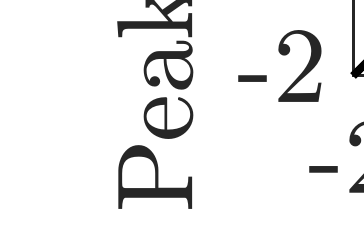



A = mdl.Coefficients.Estimate("WinterTemp");
B = mdl.Coefficients.Estimate("Precipitation");
% C = mdl.Coefficients.Estimate("Snowmelt");
D = mdl.Coefficients.Estimate("(Intercept)");
% RHS = A.*WinterTemp + B.*Precipitation + C.*Snowmelt + D;
% RHS = A.*WinterTemp + C.*Snowmelt  + D;
RHS = A.*WinterTemp + B.*Precipitation  + D;
f1 = figure; 
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
errorbar(RHS,mRRD,erzscore,'.k','MarkerSize',90,'LineWidth',4)
hold on

for l = 1:numel(years)
    hold on
    plot(RHS(l),mRRD(l),'.','MarkerSize',35*2,'Color',Colors(l,:))
end
plot([-2 2],[-2 2],'-k',LW{[1,5]})
set(gca, LW{[1,4]},'XLim',[-2,2],'Ylim',[-2,2],TL{:},FS{[1,4]});
axis square
% axis equal




xlabel('Model fit [nondim] ',TX{:},FS{[1,4]},UN{[1,3]})
ylabel('Peak RRD [nondim] ',TX{:},FS{[1,4]},UN{[1,3]})

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'modelfit_nondimensional' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end


% %%%% Testing out making leverage plots using jmp method. 
f1 = figure

f1 =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axh axh]);
hold on;
hout = plotAdded(mdl,"WinterTemp",'Color','blue','MarkerSize',35*2,'Marker','.','LineWidth',12)

hout =   3×1 Line array:

  Line    (data)
  Line    (fit)
  Line    (95% conf. bounds)


xvar = hout.XData;
yvar = hout.YData;
errorbar(xvar,yvar,erzscore,'.k','MarkerSize',45*2,'LineWidth',4)
% plot(xvar,yvar,'.','MarkerSize',45*2,'Color','black')
for l = 1:numel(years)
    hold on
plot(xvar(l),yvar(l),'.','MarkerSize',35*2,'Color',Colors(l,:))
end
hold off;  % Use 'hold off' to stop adding plots to the same figure
legend off
xlabel('Adj. winter $\&$ spring temp [nondim]',TX{:},FS{[1,4]},UN{[1,3]})
ylabel('',TX{:},FS{[1,4]},UN{[1,3]})
title('',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,LW{[1,4]},'XLim',[-2,2],'YLim',[-2,2], TL{:},FS{[1,4]}, 'Box', 'on');
hLineTokens = findobj(hout, 'Type','Line');
set(hLineTokens, 'LineWidth', 12);

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'addedplot_WinterTemp' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end


f1 = figure

f1 =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axh axh]);

hout=plotAdded(mdl,"Precipitation",'Color','blue','MarkerSize',35*2,'Marker','.','LineWidth',12)

hout =   3×1 Line array:

  Line    (data)
  Line    (fit)
  Line    (95% conf. bounds)


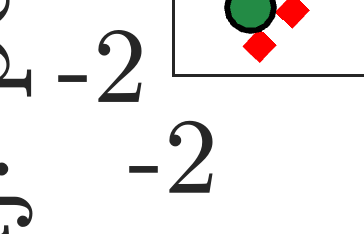

xvar = hout.XData;
yvar = hout.YData;
hold on
errorbar(xvar,yvar,erzscore,'.k','MarkerSize',45*2,'LineWidth',4)
% plot(xvar,yvar,'.','MarkerSize',45*2,'Color','black')
for l = 1:numel(years)
    hold on
plot(xvar(l),yvar(l),'.','MarkerSize',35*2,'Color',Colors(l,:))
end
hLineTokens = findobj(hout, 'Type','Line');
set(hLineTokens, 'LineWidth', 12);
legend off
hold off;  % Use 'hold off' to stop adding plots to the same figure

xlabel('Adj. summer rainfall [nondim]',TX{:},FS{[1,4]},UN{[1,3]})
ylabel('Adj. peak RRD [nondim]',TX{:},FS{[1,4]},UN{[1,3]})
title('',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,LW{[1,4]},'XLim',[-2,2],'YLim',[-2,2],TL{:},FS{[1,4]});
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'addedplot_precip' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

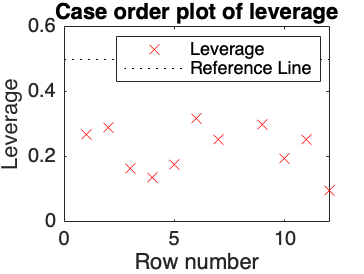

figure

plotDiagnostics(mdl)
legend('show') % Show the legend



% Get leverage values
leverage = mdl.Diagnostics.Leverage;

% Define vector for x-axis values
myVector = years;



% Create new figure
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

% Plot vector against leverage values
for ll = 1:numel(years)
plot(years(ll), leverage(ll), '.','MarkerSize',35*2,'Color',Colors(ll,:));
hold on
end
yline(0.5,'-.')

xlabel('Years',TX{:},FS{[1,4]},UN{[1,3]})
ylabel('Leverage',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,TL{:},FS{[1,4]});
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'years_leverage' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

## Save files to txt

%First make a table
WinterTemp = av_winter'; 
Precipitation = totalP'; 
mRRD = maxRRD';
zWinterTemp = zscore(av_winter)'; 
zPrecipitation = zscore(totalP)'; 
zmRRD = zscore(maxRRD)';
years = years';
Mtxt = table(years,WinterTemp,Precipitation,mRRD,...
    zWinterTemp,zPrecipitation,zmRRD);
writetable(Mtxt,'ModelParams','WriteRowNames',true,'Delimiter',',');
    TDat = [WinterTemp,Precipitation,mRRD];

% ModelParams = readtable("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years/ModelParams.txt");
% P = ModelParams.Precipitation;
% years = ModelParams.years;
% mRRD = ModelParams.mRRD;
% xlevWinter = ModelParams.XLeverageOfWinterTempForMRRD;
% ylevWinter = ModelParams.YLeverageOfWinterTempForMRRD;
% xlevPrecip = ModelParams.XLeverageOfPrecipitationForMRRD;
% ylevPrecip = ModelParams.YLeverageOfPrecipitationForMRRD;
% f1 = figure;
% yearsplots(xlevWinter,ylevWinter,years,maxRRDse,'Winter $\&$ Spring Temp Residual[$^{\circ}$ C]','Peak Runoff Response Residual [1/hr]','Leverage Plot',1,1)
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'WSTLeverage' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f1,format,resl,rend,figname,'-loose');
% end
% f2 = figure;
% yearsplots(xlevPrecip,ylevPrecip,years,maxRRDse,'Rainfall Residual [mm/month]','Peak Runoff Response Residual [1/hr]','Leverage Plot',1,1)
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'RainfallLeverage' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f2,format,resl,rend,figname,'-loose');
% end

% fig1 = figure;
% yearsplots(Precipitation,WinterTemp,years,zeros(size(years)),'Precipitation [mm/hr]','Average W $\&$ S T [$^{\circ}$ C]','',1,0);
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'PrecipWinter' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(fig1,format,resl,rend,figname,'-loose');
% end
